K=10;
Z=[-10 -10];
P=[-1 -0.3-1i -0.3+1i];
sys=zpk(Z,P,K)

sys =
 
         10 (s+10)^2
  -------------------------
  (s+1) (s^2 + 0.6s + 1.09)
 
Continuous-time zero/pole/gain model.



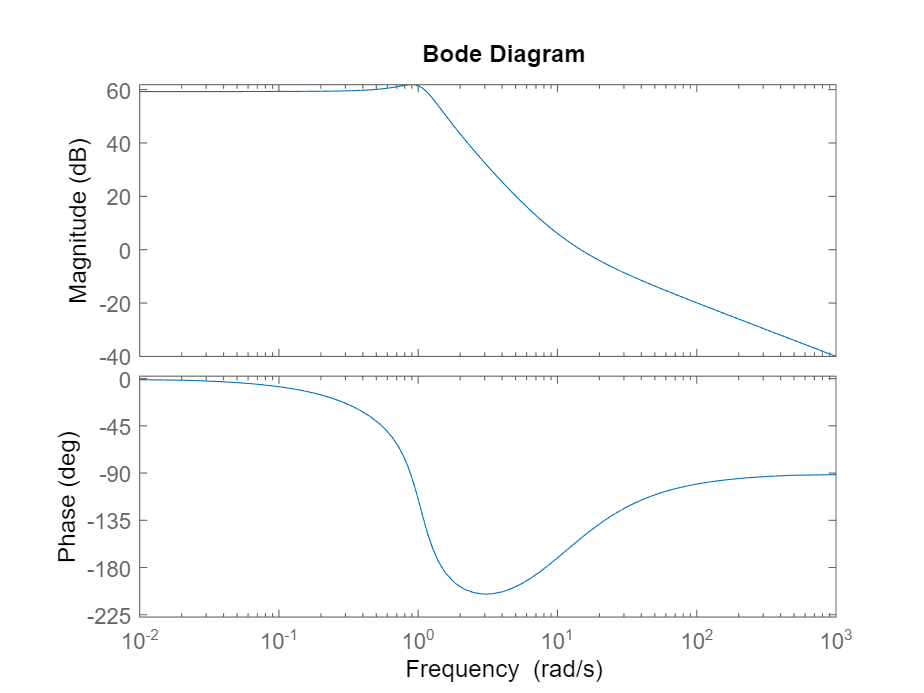

bode(sys)

Unstable for freq 1.48 do 8.22 rad/s

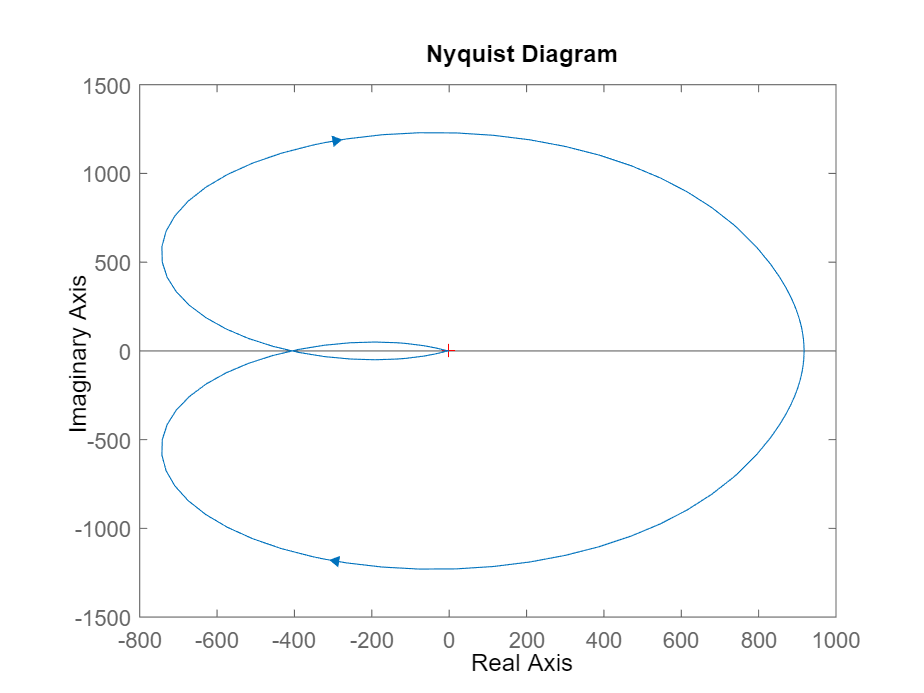

nyquist(sys)

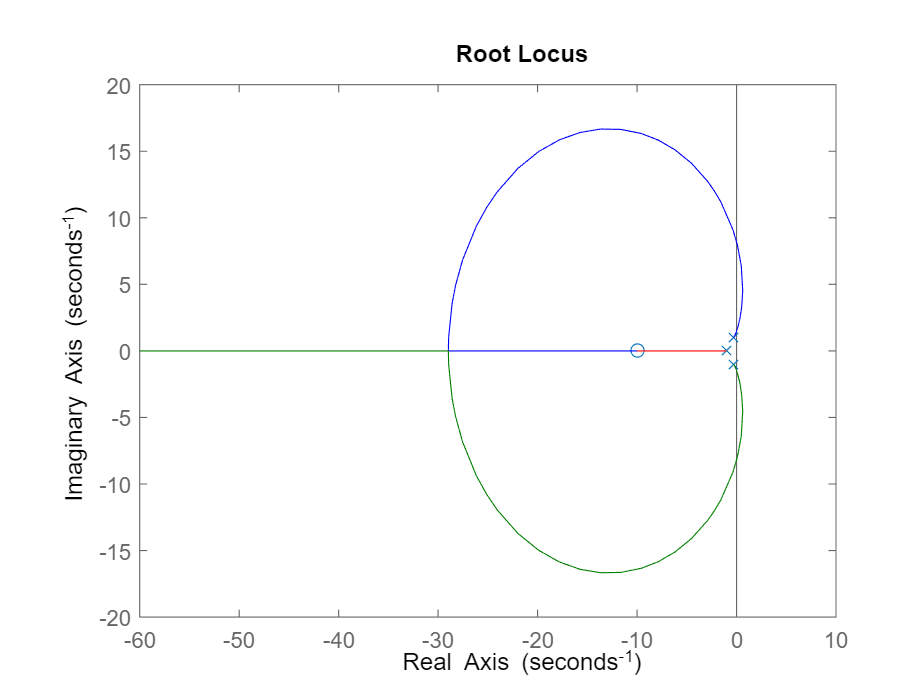

rlocus(sys)

Stable for k=(0,0.002)U(0.326,+inf)

K1=0.06;
K2=20;
sys1=zpk(Z,P,K1)

sys1 =
 
        0.06 (s+10)^2
  -------------------------
  (s+1) (s^2 + 0.6s + 1.09)
 
Continuous-time zero/pole/gain model.



H=feedback(sys1,1);
sys2=zpk(Z,P,K2)

sys2 =
 
         20 (s+10)^2
  -------------------------
  (s+1) (s^2 + 0.6s + 1.09)
 
Continuous-time zero/pole/gain model.



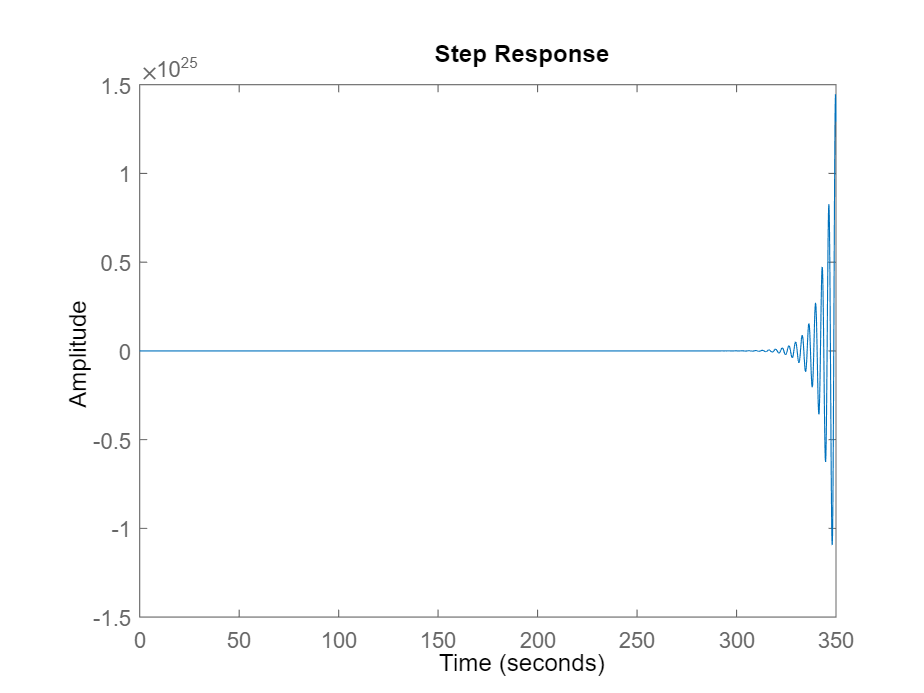

step(H)

H=feedback(sys2,1)

H =
 
            20 (s+10)^2
  --------------------------------
  (s+6.613) (s^2 + 14.99s + 302.6)
 
Continuous-time zero/pole/gain model.



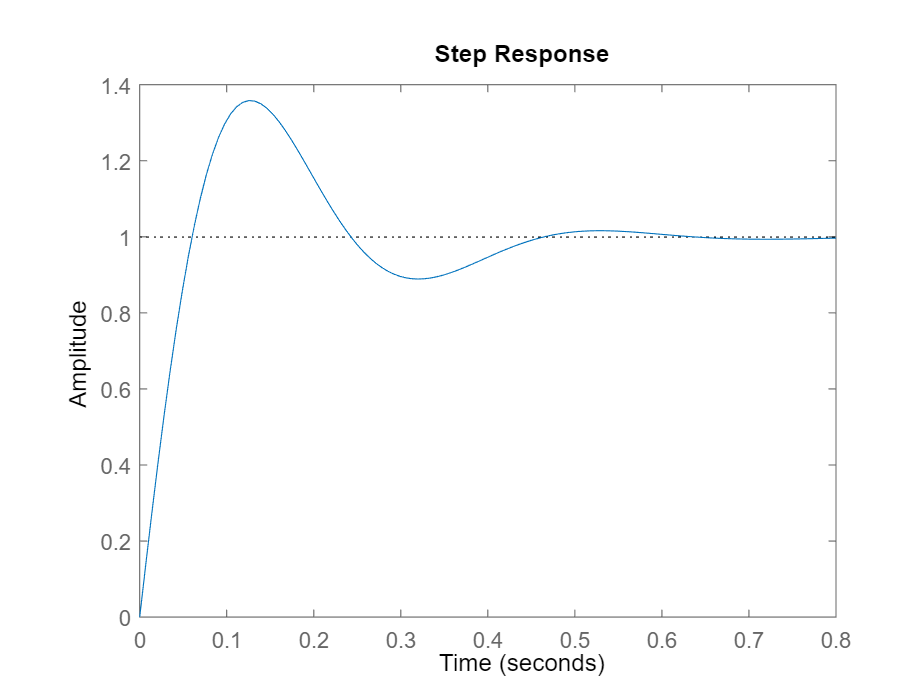

step(H)